## Group 21 - 2024 - 22051 - Final Group Assignment

% Name of specs file
filename = 'global_specs.txt';

% Settings to adjust
STFT_res = 40;
spectrogram_floor = -inf; % in dB | (-inf) to let Matlab autoscale
effective_length = 0.5;   % in decimal format

% Pass data from specs file to params struct
params = ReadFile(filename);

Non-comment lines:
    {'wav'}    {'animal_call.wav'}    {'20000'}    {'tone'}    {'10000'}    {'3'}    {'0.5'}    {'1000, 2000, 4000, 8000'}    {'0.5'}    {'hann'}    {'50'}    {'iir'}    {'2'}    {'butterworth'}    {'lp'}    {'900'}    {'2'}    {'1'}    {'log'}    {'log'}    {'nyquist'}    {'40'}

Chosen signal:
wav
Filename:
animal_call.wav
Target sampling frequency:
       20000

Generated signal type:
tone
Generator sampling frequency:
       10000

Generated signal duration:
     3

Spectral resolution:
    0.5000

Window type:
hann
Overlap:
    50

Filtering method:
iir
Filter order:
     2

Approximation method:
butterworth
Filter type:
lp
Cut-off frequencies:
   900

X-axis time limit:
     2

Y-axis amplitude limit:
     1

X-axis scaling:
log
Y-axis scaling:
log
X-axis frequency limit:
       10000

Y-axis spectral amplitude limit:
    40



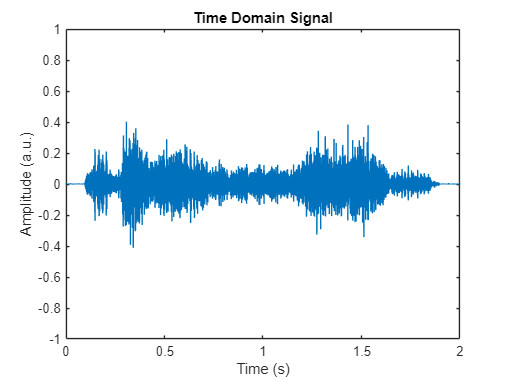

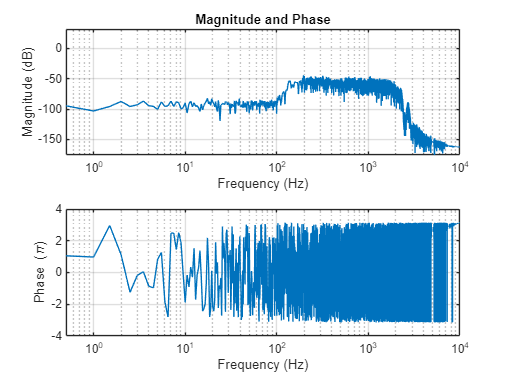

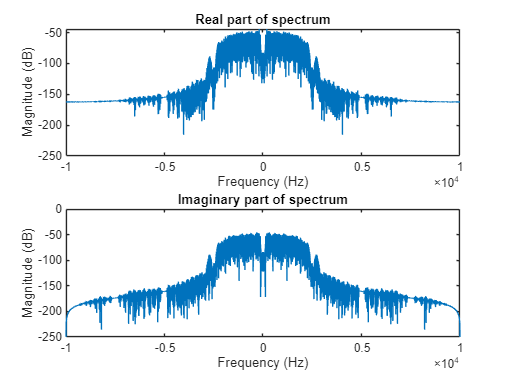

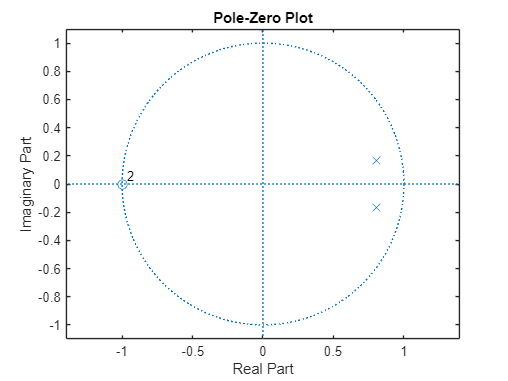

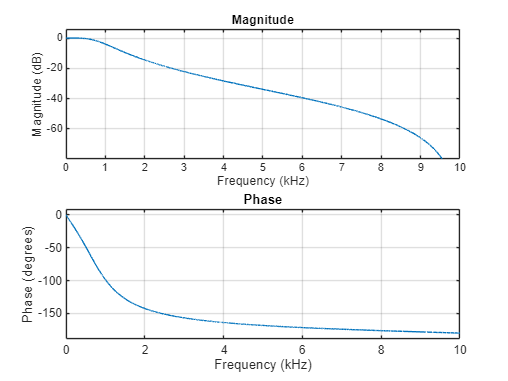

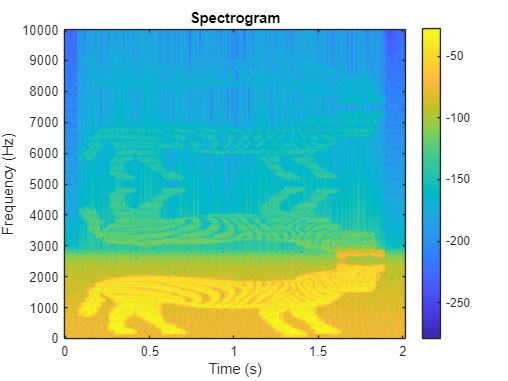


% Check if the user wants to generate a signal
if strcmp(params.chosen_signal,'generate')
    [signal,t]=generate_signal1(params);
    Fs=params.generator_fs;
    audiowrite("inputsignal_generated.wav", signal, Fs);
end

% Check if the user wants to read a file
if strcmp(params.chosen_signal,'wav')
    filePath = params.filename;
    [signal, Fs] = audioread(filePath);
    signal=resample(signal,params.target_fs,Fs);
    Fs=params.target_fs;
    t=0:1/Fs:length(signal)*(1/Fs)-(1/Fs);
end

% Design the filter, pass the signal through it and write the new output file
[B, A] = design_filter(params, effective_length, Fs);
signal = filter(B, A, signal);
audiowrite("outputsignal.wav", signal, Fs);

% Analyse frequencies and plot the data
[DFT_Y, DFT_f, STFT_Y, STFT_f, STFT_t]=frequency_analyser(signal, params, STFT_res, Fs, spectrogram_floor);
plotting(signal, t, B, A, DFT_Y, DFT_f, STFT_Y, STFT_t, STFT_f, params, Fs)


% Finally, save numerator and denominator coefficients
save('numerator_coefficients.txt', 'B', '-ascii');
save('denominator_coefficients.txt', 'A', '-ascii');